clc, clear, close all

Definimos las variables articulares del robot, para nuestro caso se tienen 4 articulaciones rotacionates, y el ultimo motor controla el agarre:

q1 = 1;
q2 = 1;
q3 = 1;
q4 = 1;

Asi Mismo las longitudes que se toman del robot son las siguientes:

L1 = 45; %mm
L2 = 105.46; %mm
L3 = 106; %mm
L4 = 64.72; 

% DH =[THETA  D   A   ALPHA   SIGMA OFFSET] 
DH = [q1  	  L1  0	  pi/2	  0	     0;
      q2	  0	  L2  0	      0	     pi/2;
      q3	  0	  L3  0	      0	     0;
      q4	  0	  L4  0	      0	     0];

for i=1:size(DH)
    L(i) = Link(DH(i,:));
end

PX = SerialLink(L,'name','Firulo','tool',trotx(-pi/2)*troty(pi/2))

 
PX = 
 
Firulo (4 axis, RRRR, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         45|          0|      1.571|          0|
|  2|         q2|          0|      105.5|          0|      1.571|
|  3|         q3|          0|        106|          0|          0|
|  4|         q4|          0|      64.72|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =   0  0  1  0             
          0         0  1  0  0           -1  0  0  0             
       9.81         0  0  1  0            0 -1  0  0             
                    0  0  0  1            0  0  0  1             


%PX = SerialLink(L,'name','Firulo')
%% Transformation matrices
syms  q1 q2 q3 q4 q5 
HTB = vpa(PX.fkine([q1 q2 q3 q4]))

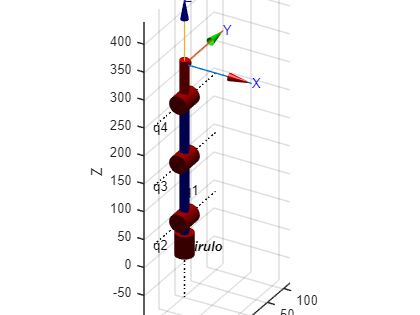



%% Plots
q  = [0 0 0 0];
figure
title('Home position')
PX.plot(q,'xyz','jaxes','notiles','floorlevel',0,'noshadow')
axis tight
view([30 30])

figure(2)

title(['$$q=\left[\matrix{\frac{-\pi}{9}&\frac{\pi}{9}&\frac{-\pi}{9}&' ...
    '\frac{\pi}{9}&0}\right]$$'],...
      'interpreter','latex')

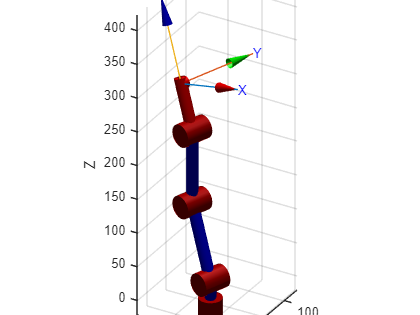


PX = SerialLink(PX,'name','PX1');
PX.plot([-pi/9 pi/9 -pi/9 pi/9],'xyz','notiles','floorlevel',0,'noshadow','noname')
axis tight
view([30 30])

figure(2)

title(['$$q=\left[\matrix{\frac{\pi}{6}&\frac{-\pi}{6}&\frac{\pi}{6}&' ...
    '\frac{-\pi}{6}&0}\right]$$'],...
      'interpreter','latex')

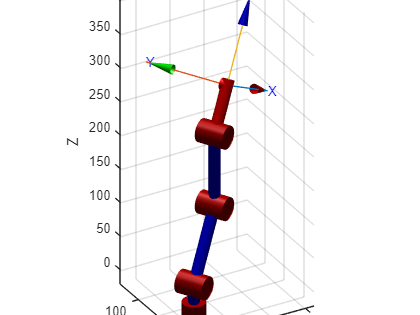


PX = SerialLink(PX,'name','PX2');
PX.plot([pi/6 -pi/6 pi/6 -pi/6],'xyz','notiles','floorlevel',0,'noshadow','noname')
axis tight
view([-30 30])


figure(2)

title(['$$q=\left[\matrix{\frac{-\pi}{2}&\frac{\pi}{12}&\frac{-11\pi}{36}&' ...
    '\frac{17\pi}{180}&0}\right]$$'],...
      'interpreter','latex')

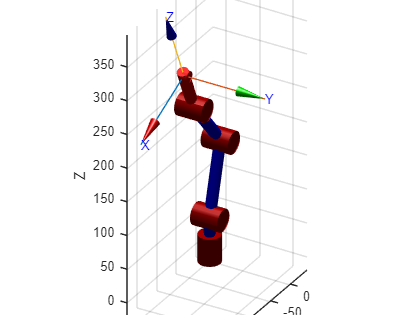

PX = SerialLink(PX,'name','PX3');
PX.plot([-pi/2 pi/12 -55*pi/180 17*pi/180],'xyz','notiles','floorlevel',0,'noshadow','noname')
axis tight
view([30 30])


figure(2)

title(['$$q=\left[\matrix{\frac{\pi}{2}&\frac{\pi}{4}&\frac{-11\pi}{36}&' ...
    '\frac{\pi}{4}&10}\right]$$'],...
      'interpreter','latex')

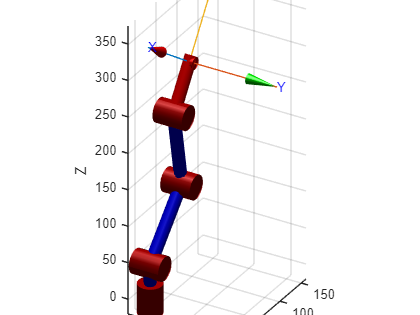


PX = SerialLink(PX,'name','PX4');
PX.plot([-pi/2 pi/4 -55*pi/180 pi/4],'xyz','notiles','floorlevel',0,'noshadow','noname')
axis tight
view([30 30])

figure(2)

title(['$$q=\left[\matrix{\frac{\pi}{9}&\frac{\pi}{9}&\frac{\pi}{9}&' ...
    '\frac{\pi}{9}&0}\right]$$'],...
      'interpreter','latex')

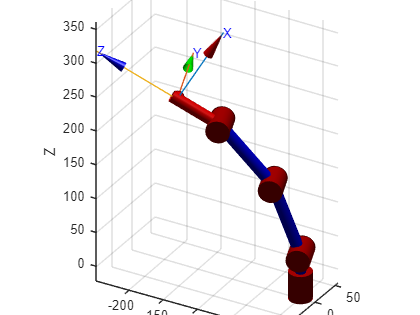


PX = SerialLink(PX,'name','PX1');
PX.plot([pi/9 pi/9 pi/9 pi/9],'xyz','notiles','floorlevel',0,'noshadow','noname')
axis tight
view([30 30])